a = 0;
b = 2;
alpha = 0;
beta = 1;

xmesh = linspace(a,b,2);
ymesh = linspace(a,beta,2);
solinit = bvpinit(xmesh, @guess);

sol = bvp4c(@bvpfcn, @bcfcn, solinit);

figure
plot(sol.x, sol.y(1,:), '-o')
hold on

x_cpp = linspace(0,2,11)

x_cpp =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000


x_cpp = x_cpp(2:end-1)

x_cpp =     0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000


cpp_res =     [ 0.00417463
     -0.0173886
     -0.0526046
     -0.0866577
      -0.101431
      -0.074815
      0.0198568
        0.21289
       0.533184]

cpp_res =     0.0042
   -0.0174
   -0.0526
   -0.0867
   -0.1014
   -0.0748
    0.0199
    0.2129
    0.5332


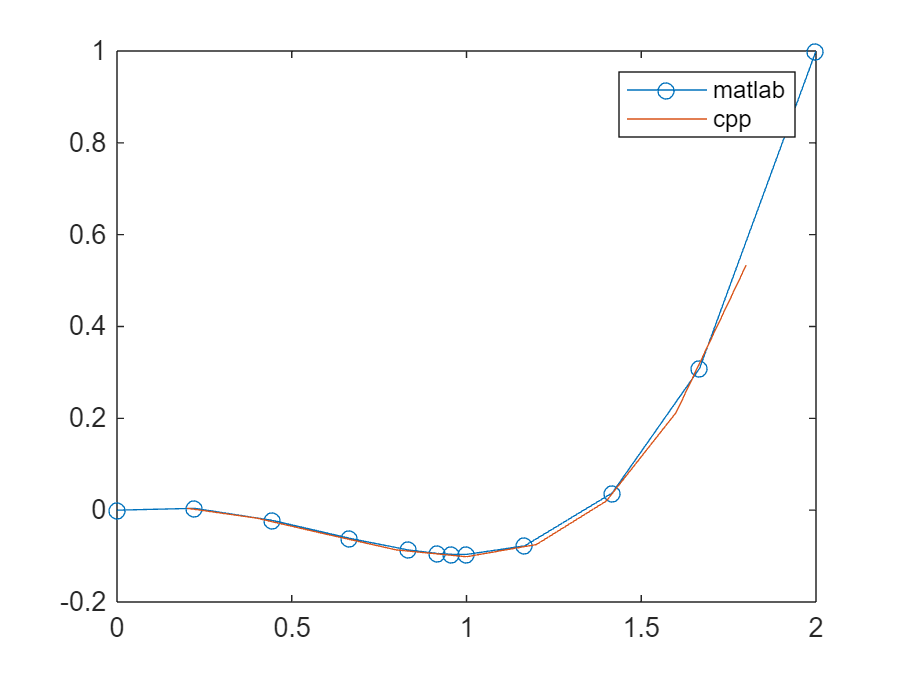

plot(x_cpp,cpp_res)
legend("matlab", "cpp")

function dydx = bvpfcn(x,y)
dydx = [y(2)
       2*x+sin(y(2))-cos(y(1))];
end

function res = bcfcn(ya,yb)
res = [ya(1)
       yb(1)-1];
end

function g = guess(x)
g = [sin(x)
     cos(x)];
end